# Decentralized OPF

clearVars = true;
localUsername = getenv('USERNAME');
listOfUsernames = {'aryan', 'Aryan Ritwajeet Jha'};
if ismember(localUsername,  listOfUsernames)
    % For user 'aryan', change the current directory to the specified path
    cd(strcat("C:\Users\", localUsername, "\Documents\documents_general\dablab_files\DOPF_1Phase_dablab\"))
    addpath('functions\')
else
    fprintf("Are you not me? Might want to add the folder to the path or add folder to the workspace.\n");
end
addDirectories;

clearVariables(clearVars);

start = tic;
    
systemName = 'ieee123'

systemName = 'ieee123'

numAreas = 4

numAreas = 4

systemDataFolder = strcat("rawData/", systemName, "/numAreas_", num2str(numAreas), "/");

actualBusNums = [1:36, 119, 126, 127, 117, 54:68, 122, 118, 37:53, 120, 125, 128, 69:116, 121, 123, 124]';
N = max(actualBusNums);

loss_min = true;   % CVR  = 0, Loss minimization = 1;
itrMax = 20; % Max no. of permissible iterations for optimizing an area
% Stopping Criterion:
eps = 0.001 ; % Tolerance
displayTables = false;
displayNetworkGraphs = true;
displayActualBusNumbersInGraphs = false;
saveNetworkGraphPlots = true;
saveSimulationResults = true;
displaySimulationResultPlots = true;
saveSimulationResultPlots = true;

CVR = [0; 0]; % as opposed to [0.6; 3.0]

load_mult = 1;
gen_mult = 1;

verbose = true;
V_min = 0.95;
V_max = 1.05;

kVA_B = 1000; % base kVA
kV_B = 4.16/sqrt(3);  % 2.4018

[CBMatrix, CBTable] = extractConnectionData(systemDataFolder);

numChildAreas = zeros(numAreas, 1);
numRelationships = length(CBTable.parentArea);
uniqueParents = unique(CBTable.parentArea);
numUniqueParents = length(uniqueParents);

[isLeaf, isRoot] = deal( ones(numAreas, 1) );
for relationshipNum = 1:numRelationships
    parentArea = CBTable.parentArea(relationshipNum);
    isLeaf(parentArea, 1) = 0;
    childArea = CBTable.childArea(relationshipNum);
    isRoot(childArea, 1) = 0;
    numChildAreas(parentArea) = numChildAreas(parentArea) + 1; %contains which area has how many children
end

maxConnectingBusNum = max(CBTable.conBus_parentAreaTo);
S_allRelationships = CBTable.S_childArea;

S_parent = zeros(numAreas, 1);
S_Areas = zeros(N, numAreas);
v2_parent = 1.03^2*ones(numAreas, 1);
v2 = zeros(N, numAreas);
qD_Full_Areas = zeros(N, numAreas);
N_Areas = zeros(numAreas, 1);
m_Areas = zeros(numAreas, 1);

numTimePeriods = 1;
delta_t = 0.25; % 15 minutes = 0.25 hours
etta_C = 0.80;
etta_D = 0.80;
SOC_Array = zeros(numAreas, N, numTimePeriods);
SOC_Array(:, :, 1) = 4.6655*2*ones(numAreas, N, 1)*kV_B^2/kVA_B;

#### Start with the algorithm

Plotting for Area 1:
This area has only the substation as its 'parent area'.
This area has 2 child areas, which include the Areas: Area 2 and Areas 3.


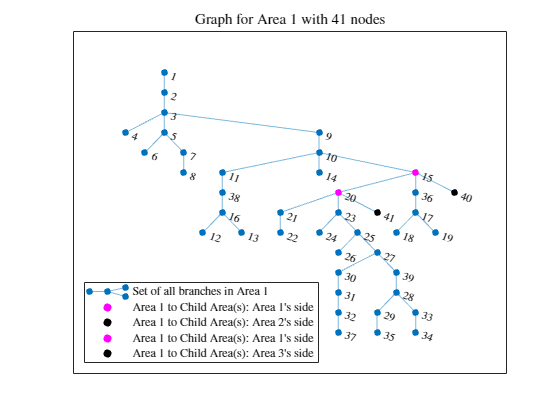

LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to satisfy the bounds.
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         237    5.278133e-04     3.596e-14     1.000e+00     0.000e+00     1.252e-03  
    1         474    5.214378e-04     5.256e-14     1.000e+00     2.530e-03     7.237e-04  
    2         711    4.905180e-04     2.220e-16     1.000e+00     1.255e-02     6.847e-04  
    3         948    3.634228e-04     2.220e-16     1.000e+00     5.779e-02     7.382e-04  
    4        1185    3.174232e-04     2.220e-16     1.000e+00     2.429e-02    

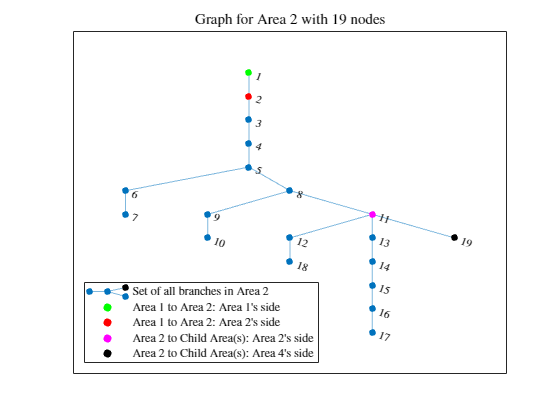

Number of DERs in Area 2 : 12.
Number of Batteries in Area 2 : 12.
First Time Period, will initialize Battery SOCs at the middle of the permissible bandwidth.
Performing Initialization Phase 1 for Area 2, Iteration #0.
LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.

Iteration 0 Area 2: Lossless Initialization WITHOUT batteries accomplished.
x0_NoLoss within limits. Phase 1 of Initialization successful. Proceeding to Phase 2 of Initialization.
Performing Initialization Phase 2 for Area 2, Iteration #0.
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         116    6.958436e-04     2.318e-15     1.000e+00     0.000e+00     1.506

table =     0.0550
    0.0550
    0.0510
    0.0470
    0.0040
    0.0020
    0.0430
    0.0040
    0.0020
    0.0390


x0 within limits. Initialization successful. Proceeding to solving for the full optimization problem.
Now solving for the real deal. Area 2 and Iteration 0
Projected savings in substation power flow by using batteries: 53.810953 percent.
Plotting for Area 3:
This area's parent is Area 1.
This area has no child areas.


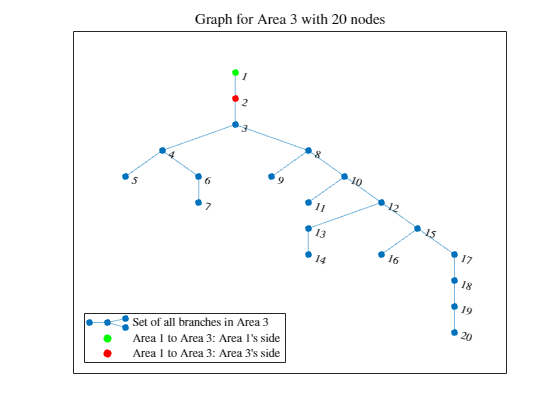

LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         129    5.093327e-04     6.181e-14     1.000e+00     0.000e+00     1.164e-03  
    1         258    5.050623e-04     1.060e-14     1.000e+00     2.069e-03     6.440e-04  
    2         387    4.840943e-04     2.220e-16     1.000e+00     1.030e-02     6.294e-04  
    3         516    3.884894e-04     2.220e-16     1.000e+00     5.033e-02     5.580e-04  
    4         645    2.937502e-04     2.220e-16     1.000e+00     5.699e-02     4.029e-03  
    5         774    2.009456e-04     2.220e-16     1.000e+00     6.628e-02     2.85

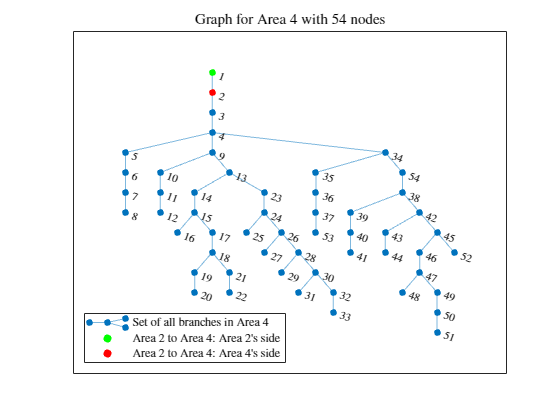

LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to satisfy the bounds.
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         341    1.463973e-03     1.288e-08     1.000e+00     0.000e+00     2.052e-03  
    1         682    1.447301e-03     4.110e-11     1.000e+00     4.093e-03     1.017e-03  
    2        1023    1.378730e-03     2.220e-16     1.000e+00     1.745e-02     1.254e-03  
    3        1364    1.301237e-03     2.220e-16     1.000e+00     2.192e-02     2.887e-03  
    4        1705    1.224138e-03     2.220e-16     1.000e+00     2.575e-02    

Still yet to converge after 0 iterations, continuing.


LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to satisfy the bounds.
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         237    1.554242e-03     5.318e-14     1.000e+00     0.000e+00     2.449e-03  
    1         474    1.535710e-03     1.206e-11     1.000e+00     4.313e-03     1.352e-03  
    2         711    1.445898e-03     2.220e-16     1.000e+00     2.140e-02     1.289e-03  
    3         948    1.222792e-03     2.220e-16     1.000e+00     5.739e-02     2.422e-03  
    4        1185    1.098343e-03     2.220e-16     1.000e+00     3.698e-02    

Still yet to converge after 1 iterations, continuing.


LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to satisfy the bounds.
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         237    2.604839e-03     4.446e-14     1.000e+00     0.000e+00     3.349e-03  
    1         474    2.576440e-03     1.047e-12     1.000e+00     5.339e-03     1.924e-03  
    2         711    2.438449e-03     2.220e-16     1.000e+00     2.650e-02     1.876e-03  
    3         948    2.132248e-03     2.220e-16     1.000e+00     6.287e-02     3.547e-03  
    4        1185    1.887187e-03     2.220e-16     1.000e+00     5.735e-02    

Still yet to converge after 2 iterations, continuing.


LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to satisfy the bounds.
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         237    2.604913e-03     3.644e-14     1.000e+00     0.000e+00     3.349e-03  
    1         474    2.576514e-03     9.545e-14     1.000e+00     5.339e-03     1.924e-03  
    2         711    2.438519e-03     2.220e-16     1.000e+00     2.650e-02     1.876e-03  
    3         948    2.132312e-03     2.220e-16     1.000e+00     6.287e-02     3.547e-03  
    4        1185    1.887247e-03     2.220e-16     1.000e+00     5.735e-02    

Still yet to converge after 3 iterations, continuing.


LP:                Optimal objective value is 0.000000.                                             


Optimal solution found.

No integer variables specified. Intlinprog solved the linear problem.

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to satisfy the bounds.
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         237    2.605022e-03     2.604e-14     1.000e+00     0.000e+00     3.349e-03  
    1         474    2.576622e-03     2.763e-13     1.000e+00     5.339e-03     1.924e-03  
    2         711    2.438622e-03     2.220e-16     1.000e+00     2.650e-02     1.876e-03  
    3         948    2.132402e-03     2.220e-16     1.000e+00     6.287e-02     3.547e-03  
    4        1185    1.887326e-03     2.220e-16     1.000e+00     5.736e-02    

Converged in 4 iterations!


for timePeriodNum = 1:numTimePeriods

    keepRunningIterations = 1;
    itr = 0;
    time_dist = zeros(itrMax, numAreas);
    microIterationLosses = zeros(itrMax, numAreas);
    R_max = zeros(itrMax, 1);
    
    Se_iter = zeros(itrMax, numAreas);
    V_iter = zeros(itrMax, N, numUniqueParents);
    
    a = [0.25 0.05]; %coefficient for correction step
    
    while keepRunningIterations
        % for Area = [2, 1 , 3:numAreas]
        for Area = 1:numAreas

            
            
            v2_parent_Area = v2_parent(Area);
            S_childAreas = S_allRelationships(CBTable.parentArea == Area);
    
            isLeaf_Area = isLeaf(Area);
            isRoot_Area = isRoot(Area);
            numChildAreas_Area = numChildAreas(Area);
            
            B0Vals_Area = SOC_Array(Area, :, timePeriodNum);
    
            [v2_Area, S_Area, qD_Full_Area, BVals_Area,...
                microIterationLosses,  ...
                itr, time_dist, R_Area, T_Area, N_Area, m_Area, nBatt_Area, busDataTable_Area, branchDataTable_Area] = ...
                NL_OPF_dist(v2_parent_Area, S_childAreas, B0Vals_Area, ...
                Area, isLeaf_Area, isRoot_Area, numChildAreas_Area, ...
                numAreas, ...
                microIterationLosses, time_dist, itr, timePeriodNum, ...
                CBTable, 'verbose', true, 'saveToFile', true);
            
            N_Areas(Area) = N_Area;
            m_Areas(Area) = m_Area;
            S_parent(Area) = S_Area(1);
            
            qD_Full_Areas(1:N_Area, Area) = qD_Full_Area;
            v2(1:N_Area, Area) = v2_Area;   % Storing all the square of the node voltages
            S_Areas(1:m_Area, Area) = S_Area;   % Storing all the S flow of the Area
    
            SOC_Array(Area, 1:nBatt_Area, timePeriodNum+1) = BVals_Area;
            
        end
        
        
        for relationshipNum = 1 : numRelationships
    
            parentArea = CBTable.parentArea(relationshipNum);
            childArea = CBTable.childArea(relationshipNum);
            parentAreaConnectingBus = CBTable.conBus_parentAreaTo(relationshipNum);
            parentAreaOutflowingPower = S_Areas(parentAreaConnectingBus - 1, parentArea);
            childAreaInflowingPower = S_parent(childArea);
    
            powerflowDifference = parentAreaOutflowingPower - childAreaInflowingPower;
    
            parentAreaConnectingBusVoltage = v2(parentAreaConnectingBus, parentArea);
            childAreaConnectingBusVoltage = v2_parent(childArea);
    
            voltageDifference = parentAreaConnectingBusVoltage - childAreaConnectingBusVoltage;
    
            R_Area = [powerflowDifference; voltageDifference];
            
            if max(abs(R_Area)) > R_max(itr+1)
                R_max(itr+1) = max(abs(R_Area));
            end
    
        end
        
        if itr > itrMax
            fprintf("Didn't converge even in %d iterations, terminating.\n", itrMax);
            keepRunningIterations = 0;
    
        elseif R_max(itr+1) < eps
            fprintf("Converged in %d iterations!\n", itr);
            keepRunningIterations = 0;
            R_max = R_max(1:itr);
    
        else
            fprintf("Still yet to converge after %d iterations, continuing.\n", itr)
            %Communication-
            
            for relationshipNum = 1:numRelationships
                parentArea = CBTable.parentArea(relationshipNum);
                childArea = CBTable.childArea(relationshipNum);
                busParentTo = CBTable.conBus_parentAreaTo(relationshipNum);
                V_iter(itr+1, busParentTo, parentArea) = v2(busParentTo, parentArea) ;
                Se_iter(itr+1,childArea) = S_parent(childArea);
    
                if itr > 2
                    v2_parent(childArea) = a(2)*V_iter(itr-1, busParentTo, parentArea)+...
                        a(1)*V_iter(itr, busParentTo, parentArea)+...
                        (1-sum(a))*v2(busParentTo, parentArea) ;
    
                    S_allRelationships(relationshipNum) = a(2)*Se_iter(itr-1, childArea)+...
                        a(1)*Se_iter(itr, childArea)+...
                        (1-sum(a))*S_parent(childArea);
                else
    
                    v2_parent(childArea) = v2(busParentTo, parentArea);
                    S_allRelationships(relationshipNum) = S_parent(childArea);
    
                end
    
            end
    
            itr = itr + 1;
    
        end
    
    end
    
    N_ParentArea_Max = max(N_Areas(uniqueParents));
    Se_iter = Se_iter(1:itr, :);
    V_iter = V_iter(1:itr, 1:N_ParentArea_Max, uniqueParents);

end

Number of nodes in Area 1 = 41.
Number of nodes in Area 2 = 19.
Number of nodes in Area 3 = 20.
Number of nodes in Area 4 = 54.


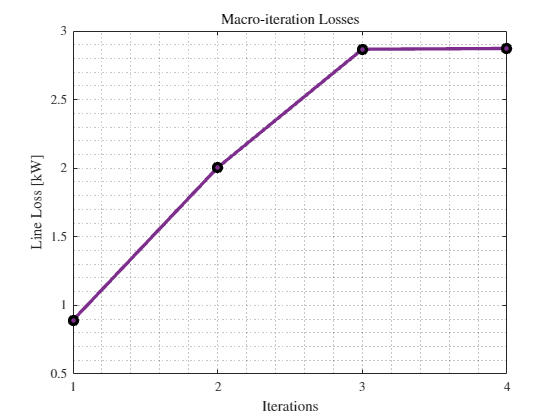

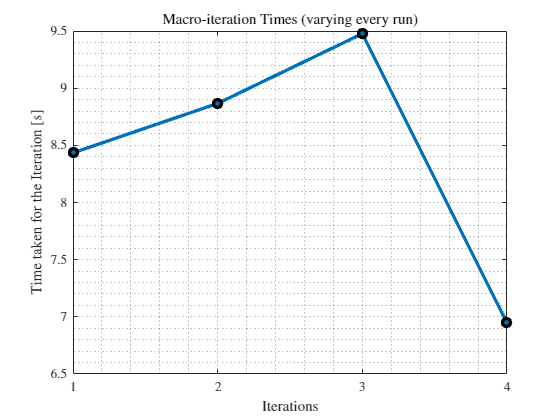

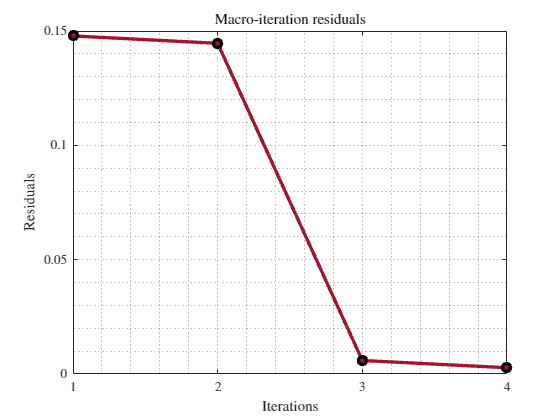

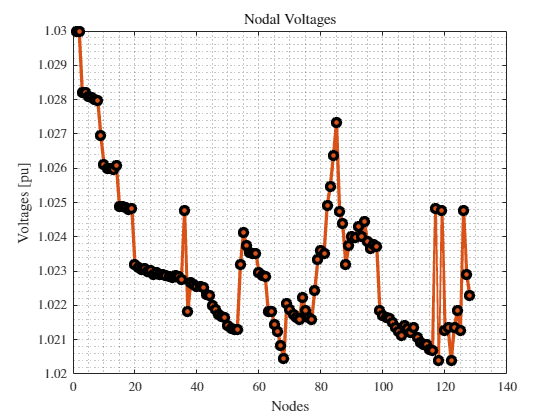

------------------------------------------------------------
Line Loss: 2.8728 kW
Substation Power: 351.8262 kW
Number of Iterations: 4
Time to Solve: 23.5071s
------------------------------------------------------------


postProcessResults(N, numAreas, N_Areas, isRoot, v2, actualBusNums, microIterationLosses, itr, time_dist, kVA_B, displaySimulationResultPlots, R_max, saveSimulationResultPlots, systemName, S_Areas, start, saveSimulationResults);